# Distributions and ROC AUC for all epochs at each orientation

downs = grabFromFilter('Downs');
ups = grabFromFilter('Ups');

%decide if you want to normalize each response to the cell's mean or max
%spike rate across epochs

normalizationOption = "mean";

allOrientations = [0:45:315];

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'; 'Moving_Grating_Direction'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'SP10'; 'Extracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

upTotalSpikesByOrientation  = cell(8, 2);
upTotalSpikesByOrientation(:, 1) = num2cell(allOrientations');
%grab data for up cells
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end

    orientations = cell2mat(loc.Analysis_Results.spikesByOrientation(:, 1)); %sometimes orientations aren't in sorted order, so go by the saved order instead and then find the right slot later
    spikesByOrientation = loc.Analysis_Results.spikesByOrientation;
    
    switch normalizationOption
        case 'max'
            maxFR = 0;
            for j = 1:size(spikesByOrientation, 1)
                rates = spikesByOrientation{j, 2};
                maxFR = max([maxFR, rates]);
            end
        case 'mean'
            maxFR = mean(loc.Analysis_Results.mean_spikesByOrientation);
        otherwise
            maxFR = 1; %divide by 1 (i.e. don't normalize)
    end
    
    for j = 1:numel(orientations)
        slot_j = allOrientations == orientations(j);
        o_j = upTotalSpikesByOrientation{slot_j, 2}; %pull out the cell array inside the cell array that holds total spikes for each epoch for each cell
        o_j{end+1, 1} = spikesByOrientation{j, 2}./maxFR; %insert total spikes for this cell for each epoch at that orientation
        upTotalSpikesByOrientation{slot_j, 2} = o_j; %put o_j back into the bigger cell array
    end
end

downTotalSpikesByOrientation  = cell(8, 2);
downTotalSpikesByOrientation(:, 1) = num2cell(allOrientations');
%grab data for down cells
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end

    orientations = cell2mat(loc.Analysis_Results.spikesByOrientation(:, 1));
    spikesByOrientation = loc.Analysis_Results.spikesByOrientation;
    
    switch normalizationOption
        case 'max'
            maxFR = 0;
            for j = 1:size(spikesByOrientation, 1)
                rates = spikesByOrientation{j, 2};
                maxFR = max([maxFR, rates]);
            end
        case 'mean'
            maxFR = mean(loc.Analysis_Results.mean_spikesByOrientation);
        otherwise
            maxFR = 1; %divide by 1 (i.e. don't normalize)
    end
    
    for j = 1:numel(orientations)
        slot_j = allOrientations == orientations(j);
        o_j = downTotalSpikesByOrientation{slot_j, 2}; %pull out the cell array inside the cell array that holds total spikes for each epoch for each cell
        o_j{end+1, 1} = spikesByOrientation{j, 2}./maxFR; %insert total spikes for this cell for each epoch at that orientation
        downTotalSpikesByOrientation{slot_j, 2} = o_j; %put o_j back into the bigger cell array
    end
end


## Begin by plotting the distributions for each orientation for both cell types

For each orientation, I am plotting the total number of spikes for every epoch for every cell. There is no averaging. ROCs are calculated between 0.5 and 1.0, with 0.5 indicating that the distributions are identical and 1.0 indicating that they are completely seperable. 0 degrees is rightward motion. 90 Degrees is upwards. 180 is leftwards. 270 is downwards.

AUCbyOrientation = zeros(1, numel(orientations));

switch normalizationOption %set histogram bin edges dynamically based on whethr the data is normalized
   case 'max'
       edgs = 0:0.1:1;
       disp("All responses are normalized to each cell's maximum response across all epochs")
   case 'mean'
       edgs = 0:0.25:2.5;
       disp("All responses are normalized to each cell's mean responses across all epochs")
   otherwise
       edgs = 0:10:160;
end

All responses are normalized to each cell's mean responses across all epochs


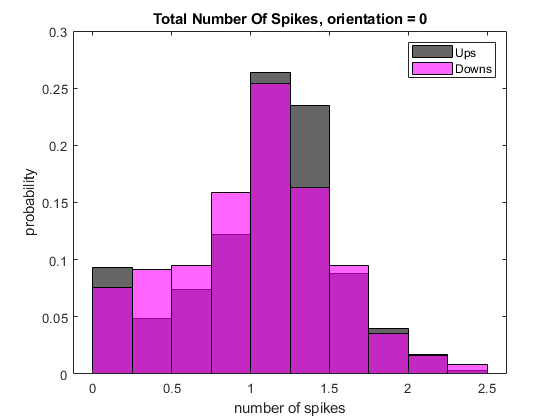

ROC AUC = 0.53502


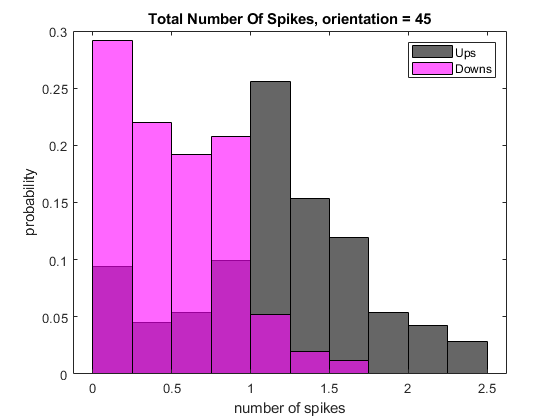

ROC AUC = 0.83175


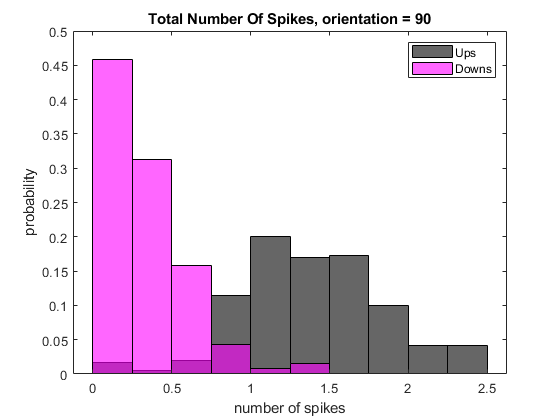

ROC AUC = 0.96978


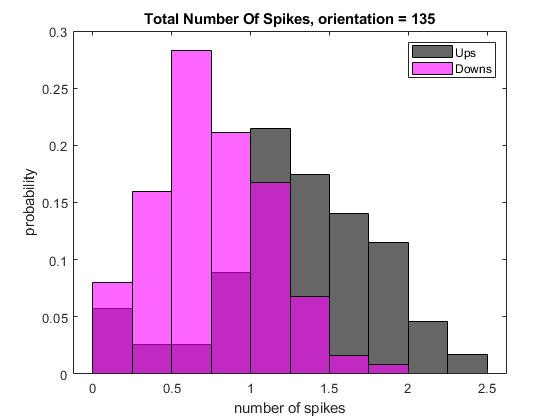

ROC AUC = 0.82022


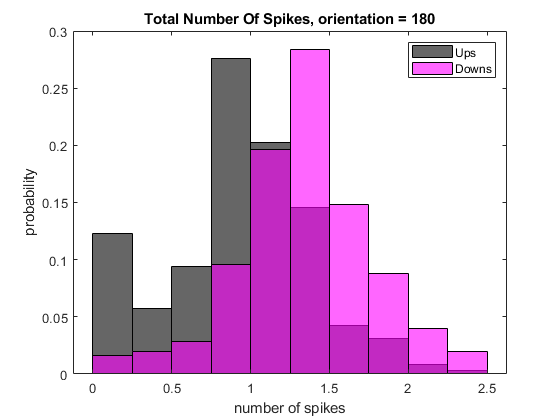

ROC AUC = 0.76593


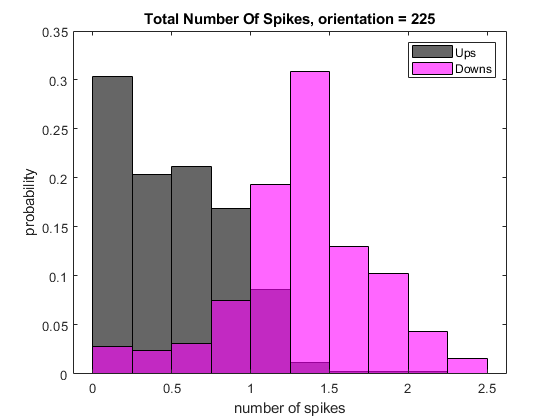

ROC AUC = 0.91524


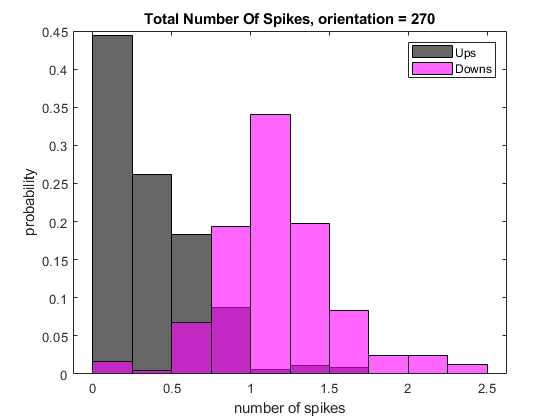

ROC AUC = 0.9527


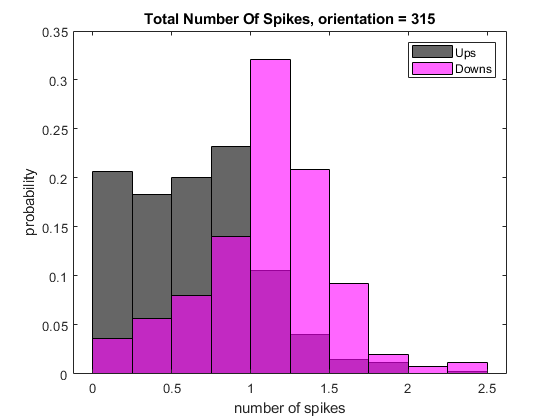

ROC AUC = 0.80184


for i = 1:numel(allOrientations)
    upAllSpikes = [];
    downAllSpikes = [];
   upSpikes = upTotalSpikesByOrientation{i, 2};
   for j = 1:size(upSpikes, 1)
       cell_j_spikeNums = upSpikes{j};
       upAllSpikes = [upAllSpikes, cell_j_spikeNums];
   end
   
    downSpikes = downTotalSpikesByOrientation{i, 2};
   for j = 1:size(downSpikes, 1)
       cell_j_spikeNums = downSpikes{j};
       downAllSpikes = [downAllSpikes, cell_j_spikeNums];
   end
   
   labels =  [zeros(1, numel(upAllSpikes)), ones(1, numel(downAllSpikes))];
   scores = [upAllSpikes, downAllSpikes];
   [~, ~, ~, AUC] = perfcurve(labels, scores, 1);
   AUC = max([AUC, 1-AUC]);
   
   AUCbyOrientation(i) = AUC;
   

   
   figure
   histogram(upAllSpikes, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization', 'probability')
   hold on
   histogram(downAllSpikes, 'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability')
   title(['Total Number Of Spikes, orientation = ', num2str(allOrientations(i))])
   legend('Ups', 'Downs')
   xlabel('number of spikes')
   ylabel('probability')
   
   disp(['ROC AUC = ', num2str(AUC)])
end

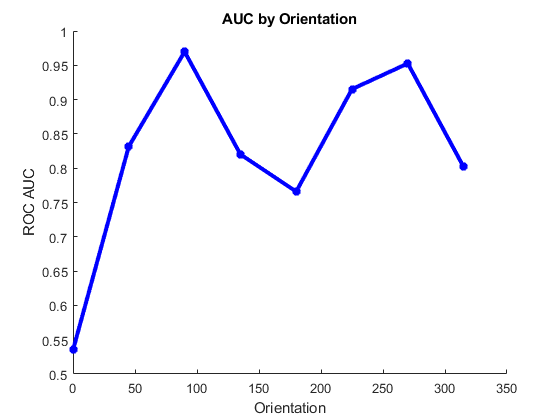

figure
title('AUC by Orientation')
hold on
plot(allOrientations, AUCbyOrientation, '-b', 'LineWidth', 3, 'Marker', '*')
xlabel('Orientation')
ylabel('ROC AUC')

Notice the asymmetry here: 270 degrees (downward motion) is easier to discriminate than 90 degrees (upward motion).

## Compare to case where there are two identical cell types

Here I'm plotting the UP cells verus a flipped version of the UP cells (i.e. "simulated ups), and the same for the down cells. This creates symmetry in that the simulated populations have identical tuning curves to the population against which they are compared.

### First Compare Normal UP cells to SIMULATED DOWN cells (i.e. flipped up cells)

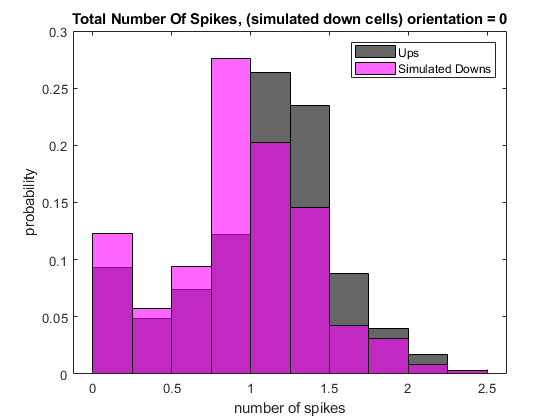

ROC AUC = 0.60252


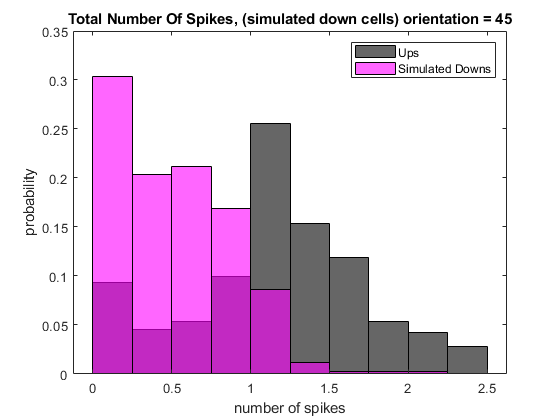

ROC AUC = 0.83272


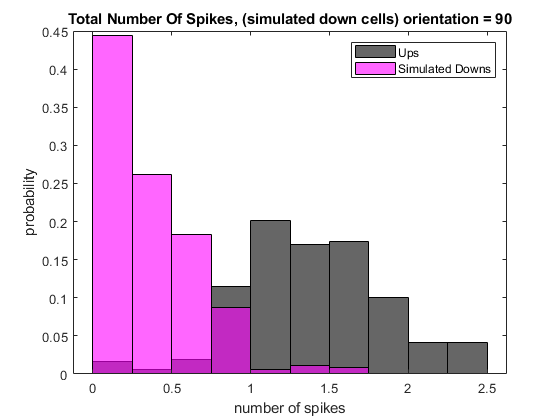

ROC AUC = 0.96761


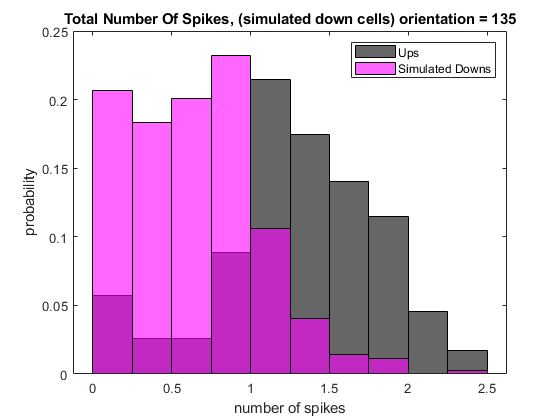

ROC AUC = 0.85418


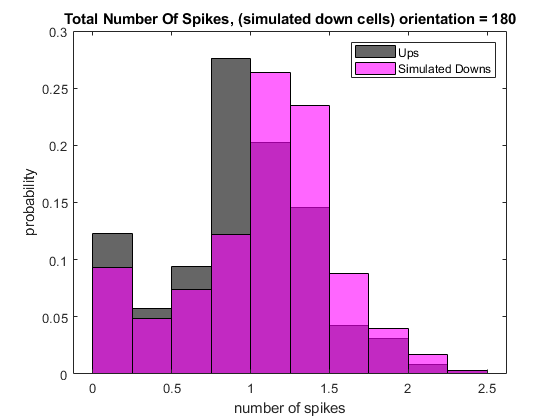

ROC AUC = 0.60252


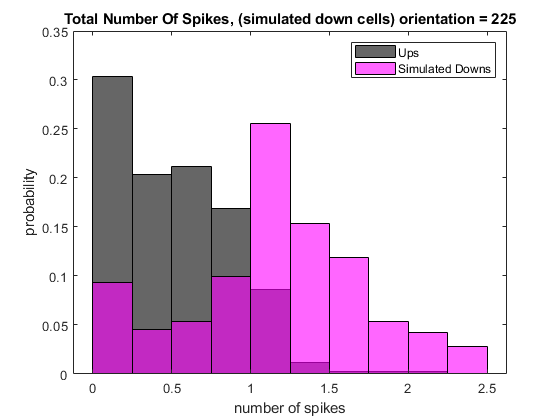

ROC AUC = 0.83272


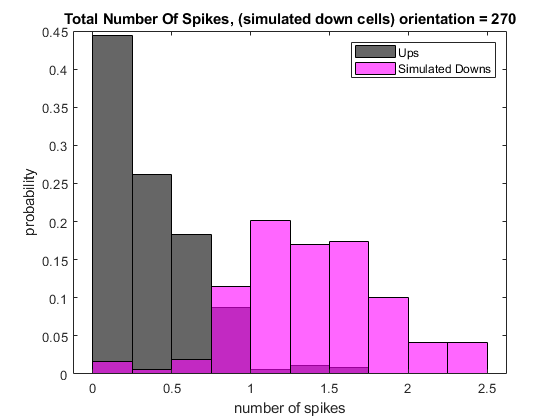

ROC AUC = 0.96761


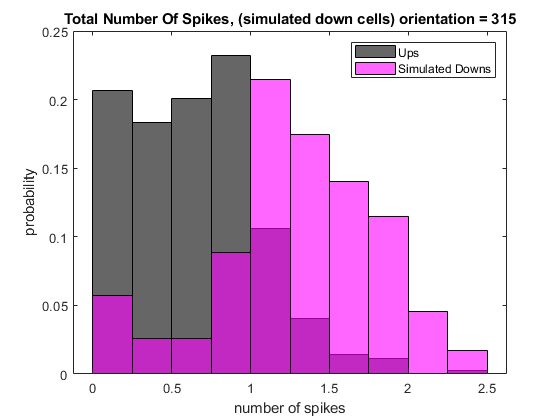

ROC AUC = 0.85418


downSIMULATED = cell(8, 2);
downSIMULATED(:, 1) = num2cell(allOrientations');

upSIMULATED = downSIMULATED;

switchOrder = [5:8, 1:4];
for i = 1:numel(allOrientations)
    downSIMULATED{switchOrder(i), 2} = upTotalSpikesByOrientation{i, 2};
    upSIMULATED{switchOrder(i), 2} = downTotalSpikesByOrientation{i, 2};
end

AUCbyOrientation_DOWNSIMULATED = zeros(1, numel(orientations));
for i = 1:numel(allOrientations)
    upAllSpikes = [];
    downAllSpikes = [];
   upSpikes = upTotalSpikesByOrientation{i, 2};
   for j = 1:size(upSpikes, 1)
       cell_j_spikeNums = upSpikes{j};
       upAllSpikes = [upAllSpikes, cell_j_spikeNums];
   end
   
   downSpikes = downSIMULATED{i, 2};
   for j = 1:size(downSpikes, 1)
       cell_j_spikeNums = downSpikes{j};
       downAllSpikes = [downAllSpikes, cell_j_spikeNums];
   end
   
   labels =  [zeros(1, numel(upAllSpikes)), ones(1, numel(downAllSpikes))];
   scores = [upAllSpikes, downAllSpikes];
   [~, ~, ~, AUC] = perfcurve(labels, scores, 1);
   AUC = max([AUC, 1-AUC]);
   
   AUCbyOrientation_DOWNSIMULATED(i) = AUC;
   
   figure
   histogram(upAllSpikes, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization', 'probability')
   hold on
   histogram(downAllSpikes, 'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability')
   title(['Total Number Of Spikes, (simulated down cells) orientation = ', num2str(allOrientations(i))])
   legend('Ups', 'Simulated Downs')
   xlabel('number of spikes')
   ylabel('probability')
   
   disp(['ROC AUC = ', num2str(AUC)])
end

### Next compare normal DOWN cells to SIMULATED UP cells (i.e. flipped down cells)

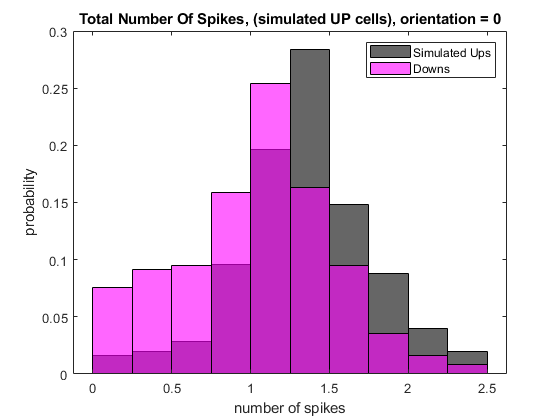

ROC AUC = 0.70355


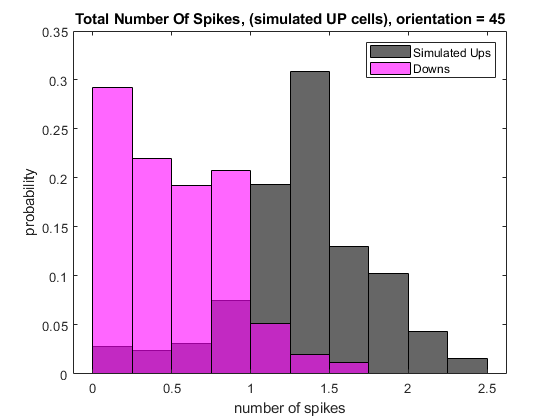

ROC AUC = 0.91587


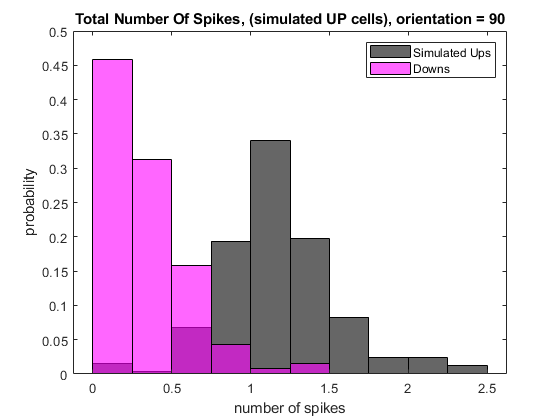

ROC AUC = 0.95762


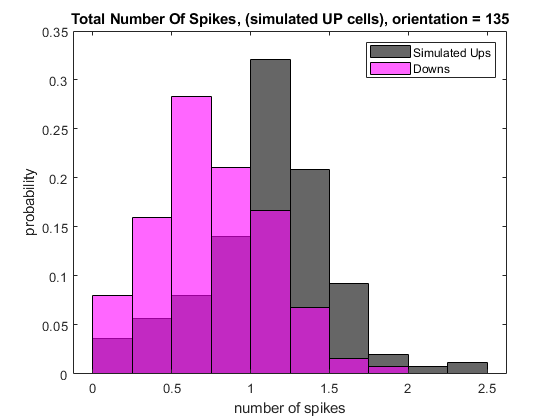

ROC AUC = 0.74523


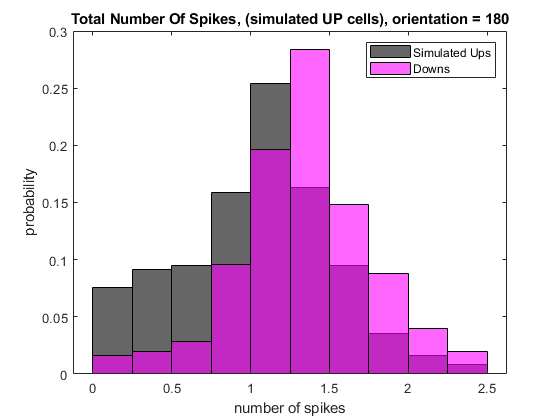

ROC AUC = 0.70355


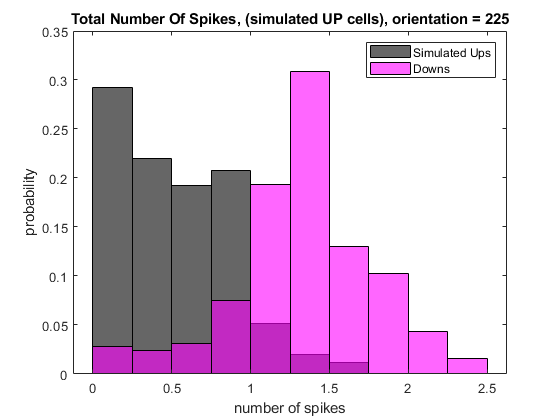

ROC AUC = 0.91587


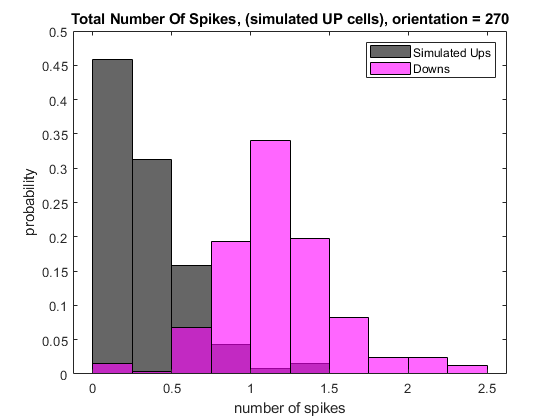

ROC AUC = 0.95762


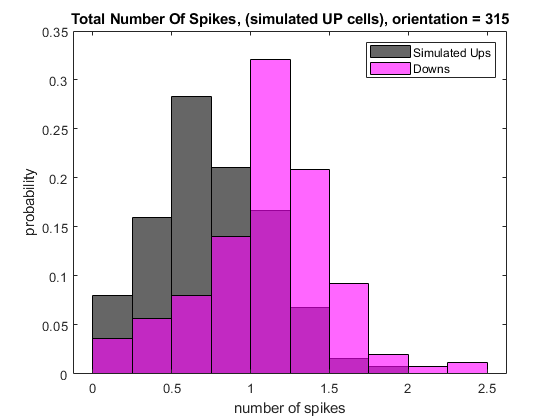

ROC AUC = 0.74523


AUCbyOrientation_UPSIMULATED = zeros(1, numel(orientations));
for i = 1:numel(allOrientations)
    upAllSpikes = [];
    downAllSpikes = [];
   
    upSpikes = upSIMULATED{i, 2};
   for j = 1:size(upSpikes, 1)
       cell_j_spikeNums = upSpikes{j};
       upAllSpikes = [upAllSpikes, cell_j_spikeNums];
   end
   
    downSpikes = downTotalSpikesByOrientation{i, 2};
   for j = 1:size(downSpikes, 1)
       cell_j_spikeNums = downSpikes{j};
       downAllSpikes = [downAllSpikes, cell_j_spikeNums];
   end
   
   labels =  [zeros(1, numel(upAllSpikes)), ones(1, numel(downAllSpikes))];
   scores = [upAllSpikes, downAllSpikes];
   [~, ~, ~, AUC] = perfcurve(labels, scores, 1);
   AUC = max([AUC, 1-AUC]);
   
   AUCbyOrientation_UPSIMULATED(i) = AUC;
   
   figure
   histogram(upAllSpikes, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization', 'probability')
   hold on
   histogram(downAllSpikes, 'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability')
   title(['Total Number Of Spikes, (simulated UP cells), orientation = ', num2str(allOrientations(i))])
   legend('Simulated Ups', 'Downs')
   xlabel('number of spikes')
   ylabel('probability')
   
   disp(['ROC AUC = ', num2str(AUC)])
end

## Comparison of AUC across all scenarios

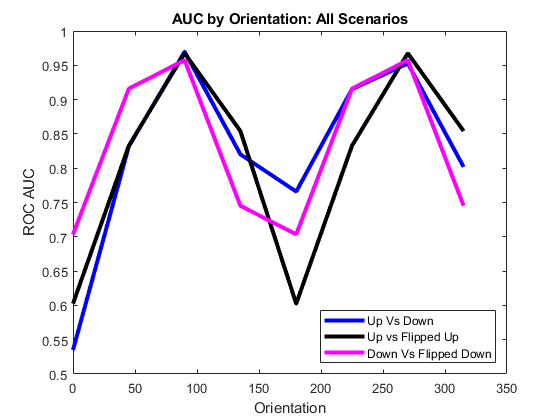

figure
plot(allOrientations, AUCbyOrientation,'-b', 'LineWidth', 3)
hold on
plot(allOrientations, AUCbyOrientation_DOWNSIMULATED,'-k', 'LineWidth', 3)
plot(allOrientations, AUCbyOrientation_UPSIMULATED,'-m', 'LineWidth', 3)
title('AUC by Orientation: All Scenarios')
lgd = legend('Up Vs Down', 'Up vs Flipped Up', 'Down Vs Flipped Down');
lgd.Location = 'southeast';
xlabel('Orientation')
ylabel('ROC AUC')

It looks to me like there are two primary impacts of asymmetry: 1) it makes upward and downward motion differentially discriminable, and 2) it increases the discriminability during horizontal motion (e.g. 180 degrees). Both effects are partially masked when normalizing each cell's responses its maximum or mean firing rate.